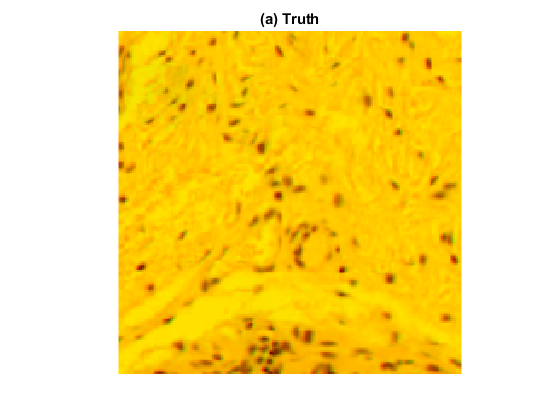

clear

load('output_images','original','unregistered','registered_cp','registered_cp_corr','imf_before','imf_cp_corr')

offsety = -2;
offsetx = 0;

winx = 100;
winy = 250;
winsize = 200;
winrangey = winy:winy+winsize;
winrangex = winx:winx+winsize;

imf_test = imfuse(original(winrangey,winrangex),registered_cp_corr(winrangey+offsety,winrangex+offsetx),'falsecolor','Scaling','joint','ColorChannels',[1 2 0]);

image(imf_test);
title('(a) Truth')
axis image
axis off